# Mohammad Reza Arani

## Convex Optimization

## 810100511

% Hw7 --> Q7
clear; clc; close all;

% Load Data:
run('one_bit_meas_data.m');


[m,n] = size(A);
A = diag(y)*A;
b = y.*b;
x = A\b; % SOlve the Linear System of Eqs.
f_prime_hist = [];
for k=1:100 % solve for 100 steps:
        w = A*x-b;
        Phi = 0.5*erfc( -w/sqrt(2) ); % MATLAB erfc() func
        Phix = 0.5*sqrt(2*pi) * erfcx(-w/sqrt(2)); % MATLAB erfcx() func
        val = -sum(log(Phi));
        Gradient = -A'* (1./Phix);
        Hessian = A'* diag((w + 1./Phix)./Phix) * A;
        v = -Hessian\Gradient;
        f_prime = Gradient'*v;
        f_prime_hist = [f_prime_hist f_prime ];
        disp("f_prime at step =  "+k + " is : ")
        disp(f_prime)
        if (-f_prime/2 < 1e-8)
            iter =k;
            disp("Solved!")
            break
        end

    t = 1;
        while ( -sum(log( 0.5*erfc(-(A*(x+t*v)-b)/sqrt(2)) )  ) > val + 0.01*t*f_prime ) 
        
        t = t/2;
        end
    x = x + t*v;
end

f_prime at step =  1 is : 


  -6.647512456315127



f_prime at step =  2 is : 


  -1.684273113499678



f_prime at step =  3 is : 


  -0.242787635885709



f_prime at step =  4 is : 


    -4.070269691846316e-04



f_prime at step =  5 is : 


    -3.911026543977576e-09



Solved!


% Answer:
disp(x')

  Columns 1 through 6

  -0.270676032856806   9.148453297062034   7.978619693215202   6.703460463844741   6.026654454532209   5.012041145168112

  Columns 7 through 10

   4.299797452899707   2.676482766549737   2.020789542898919   0.683783716891069



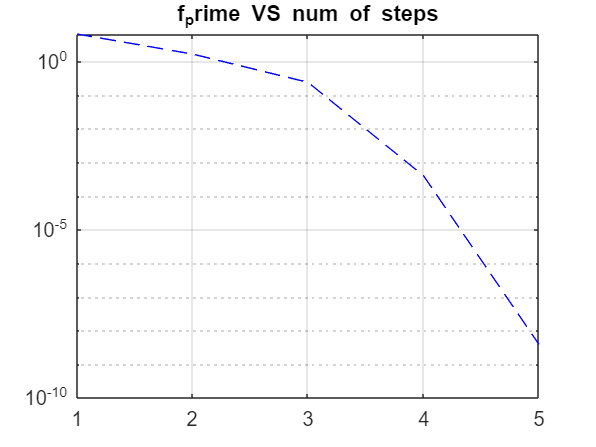

figure()
semilogy(1:iter,abs(f_prime_hist),'b--')
title('f_prime VS num of steps')
grid on